# **第十一章 生成式对抗网络**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

## **11.1 生成式对抗网络简介**

        如图1所示，一些研究发现，对于已训练好的模型，若我们在样本中加入一些细微的随机噪声，模型预测出的结果就会出现非常大的偏差，即所谓的“差之毫厘，谬之千里”。这个现象引发了广大研究人员的深入思考：模型将样本预测为某个类别标签，究竟靠的是哪部分的特征？同时，也催生出了另外一个想法：我们在训练完模型后，可以人为地产生一些”假“样本（我们肉眼看不出差异），测试模型是否会给出不同的预测结果？

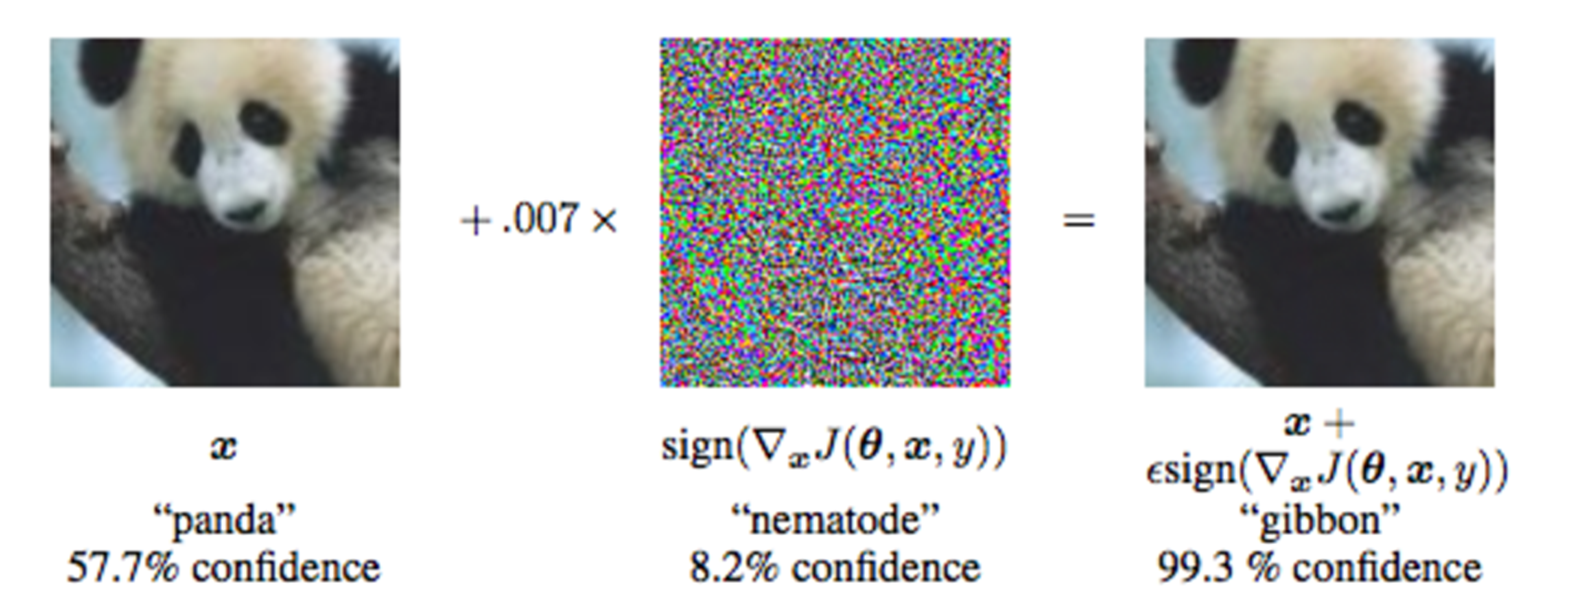

图1 对抗样本欺骗AI模型示例

        生成式对抗网络（Generative Adversarial Networks, GANs）是深度学习领域的一个重要突破，由Ian Goodfellow于2014年提出。GAN的基本思想是通过对抗过程来生成数据，这种思想在很多方面都是创新的，尤其在图像生成和处理领域展现了巨大的潜力。

        如图2所示，生成式对抗网络由两部分组成：一个生成器（Generator）和一个判别器（Discriminator）。

- **生成器（Generator）：**这部分网络负责生成数据。它从一个随机噪声向量开始，通过神经网络生成尽可能逼真的数据实例。

- **判别器（Discriminator）：**这部分网络的任务是区分生成器产生的数据和真实数据。它接受真实数据和生成数据作为输入，并尝试判断输入数据是真实的还是假的。

        生成器和判别器在训练过程中相互竞争。生成器试图生成越来越逼真的数据以欺骗判别器，而判别器则努力区分真假数据。

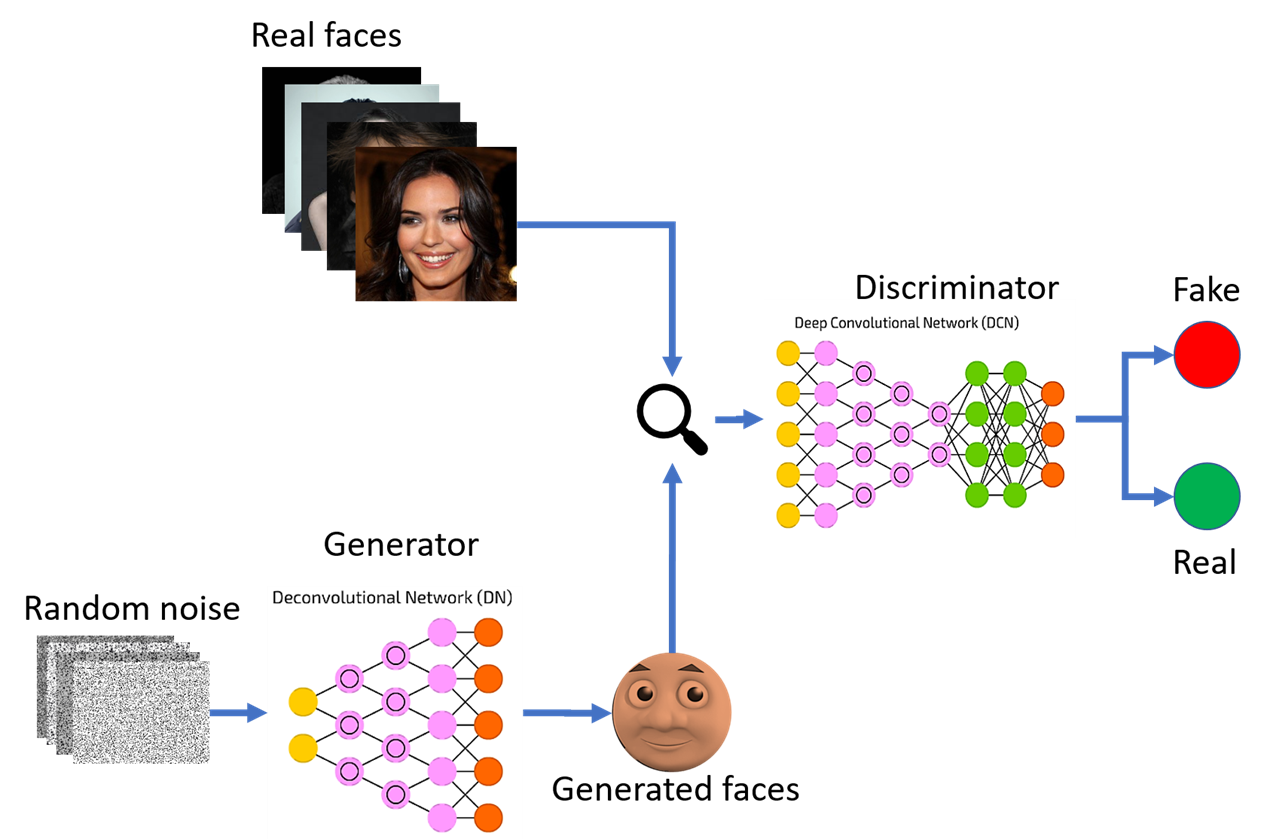

图2 生成式对抗网络拓扑结构

        生成式对抗网络模型的训练算法具体步骤如下：

- **初始化**：随机初始化生成器和判别器的网络参数。

- **判别器训练：**用一批真实数据和一批生成器生成的数据训练判别器，更新判别器的权重，以便更好地区分真假数据。

- **生成器训练：**生成一批新的数据并送入判别器，根据判别器的判断结果更新生成器的权重，目标是让生成器生成的数据更能欺骗判别器。

- **损失函数：**通常选择二元交叉熵损失函数。

- **反向传播与优化：**使用反向传播算法计算损失函数的梯度，使用优化算法（如Adam）更新两个网络的权重。

- **评估与调整：**定期评估生成的数据质量，根据需要调整模型结构或训练参数。

## 11.2 案例：基于GAN的图像生成

- **导入数据**

        导入指定路径下的图片文件。

imds = imageDatastore('roses', ...
                      'IncludeSubfolders',true, ...
                      'LabelSource','foldernames');

- **数据扩增**

        利用MATLAB自带工具箱的函数imageDataAugmenter对数据集进行一定量的扩增。

augmenter = imageDataAugmenter( 'RandXReflection',true,'RandScale',[1 2]);
augimds = augmentedImageDatastore([64 64],imds,'DataAugmentation',augmenter);

- **定义生成器网络拓扑结构**

filterSize = [4 4];
numFilters = 16;
numLatentInputs = 100;

layersGenerator = [imageInputLayer([1 1 numLatentInputs],'Normalization','none','Name','in')
                   transposedConv2dLayer(filterSize,8*numFilters,'Name','tconv1')
                   batchNormalizationLayer('Name','bn1')
                   reluLayer('Name','relu1')
                   transposedConv2dLayer(filterSize,4*numFilters,'Stride',2,'Cropping',1,'Name','tconv2')
                   batchNormalizationLayer('Name','bn2')
                   reluLayer('Name','relu2')
                   transposedConv2dLayer(filterSize,2*numFilters,'Stride',2,'Cropping',1,'Name','tconv3')
                   batchNormalizationLayer('Name','bn3')
                   reluLayer('Name','relu3')
                   transposedConv2dLayer(filterSize,numFilters,'Stride',2,'Cropping',1,'Name','tconv4')
                   batchNormalizationLayer('Name','bn4')
                   reluLayer('Name','relu4')
                   transposedConv2dLayer(filterSize,3,'Stride',2,'Cropping',1,'Name','tconv5')
                   tanhLayer('Name','tanh')];

lgraphGenerator = layerGraph(layersGenerator);
dlnetGenerator = dlnetwork(lgraphGenerator)

dlnetGenerator =   dlnetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
    Connections: [14×2 table]
     Learnables: [18×3 table]
          State: [8×3 table]
     InputNames: {'in'}
    OutputNames: {'tanh'}
    Initialized: 1

  View summary with summary.


- **定义判别器网络拓扑结构**

scale = 0.2;
layersDiscriminator = [imageInputLayer([64 64 3],'Normalization','none','Name','in')
                       convolution2dLayer(filterSize,numFilters,'Stride',2,'Padding',1,'Name','conv1')
                       leakyReluLayer(scale,'Name','lrelu1')
                       convolution2dLayer(filterSize,2*numFilters,'Stride',2,'Padding',1,'Name','conv2')
                       batchNormalizationLayer('Name','bn2')
                       leakyReluLayer(scale,'Name','lrelu2')
                       convolution2dLayer(filterSize,4*numFilters,'Stride',2,'Padding',1,'Name','conv3')
                       batchNormalizationLayer('Name','bn3')
                       leakyReluLayer(scale,'Name','lrelu3')
                       convolution2dLayer(filterSize,8*numFilters,'Stride',2,'Padding',1,'Name','conv4')
                       batchNormalizationLayer('Name','bn4')
                       leakyReluLayer(scale,'Name','lrelu4')
                       convolution2dLayer(filterSize,1,'Name','conv5')];

lgraphDiscriminator = layerGraph(layersDiscriminator);
dlnetDiscriminator = dlnetwork(lgraphDiscriminator)

dlnetDiscriminator =   dlnetwork with properties:

         Layers: [13×1 nnet.cnn.layer.Layer]
    Connections: [12×2 table]
     Learnables: [16×3 table]
          State: [6×3 table]
     InputNames: {'in'}
    OutputNames: {'conv5'}
    Initialized: 1

  View summary with summary.


- **可视化生成器与判别器网络拓扑结构**

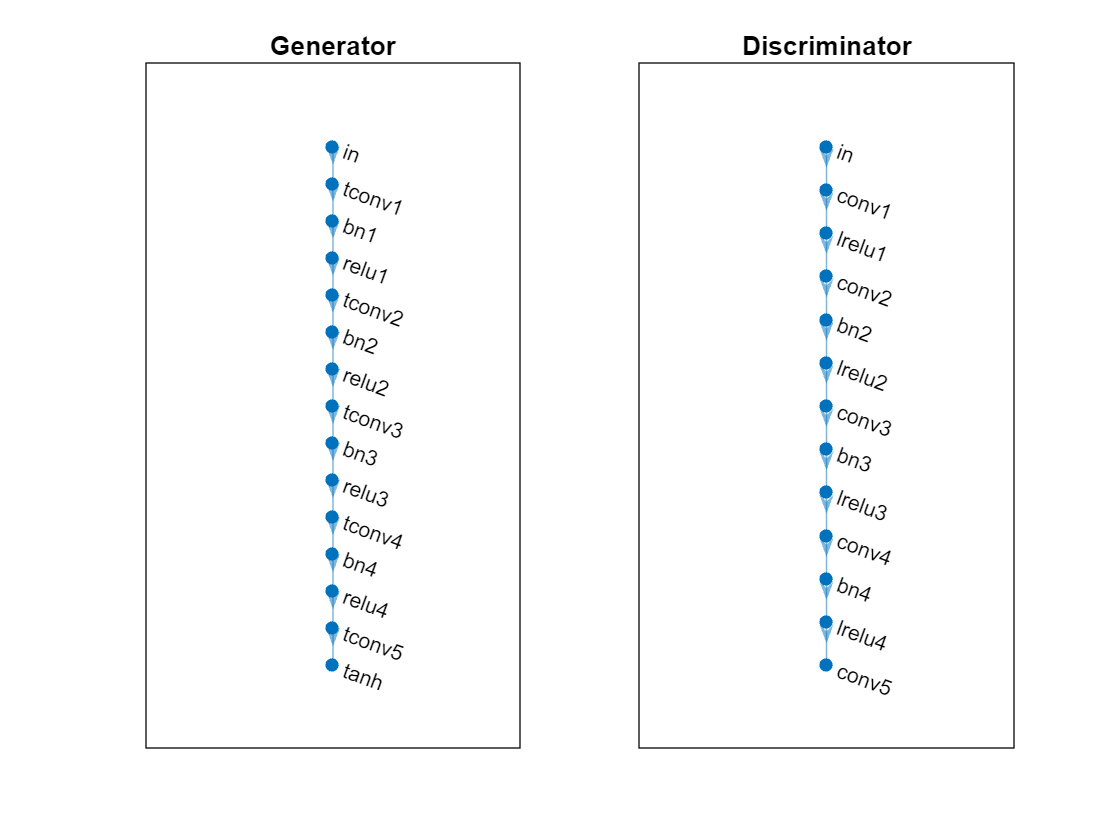

figure
subplot(1,2,1)
plot(lgraphGenerator)
title("Generator")

subplot(1,2,2)
plot(lgraphDiscriminator)
title("Discriminator")

- **设置训练参数**

numEpochs = 1000;
miniBatchSize = 128;
augimds.MiniBatchSize = miniBatchSize;

learnRateGenerator = 0.0002;
learnRateDiscriminator = 0.0001;

trailingAvgGenerator = [];
trailingAvgSqGenerator = [];
trailingAvgDiscriminator = [];
trailingAvgSqDiscriminator = [];

gradientDecayFactor = 0;
squaredGradientDecayFactor = 0.455;

executionEnvironment = "auto";

- **训练模型**

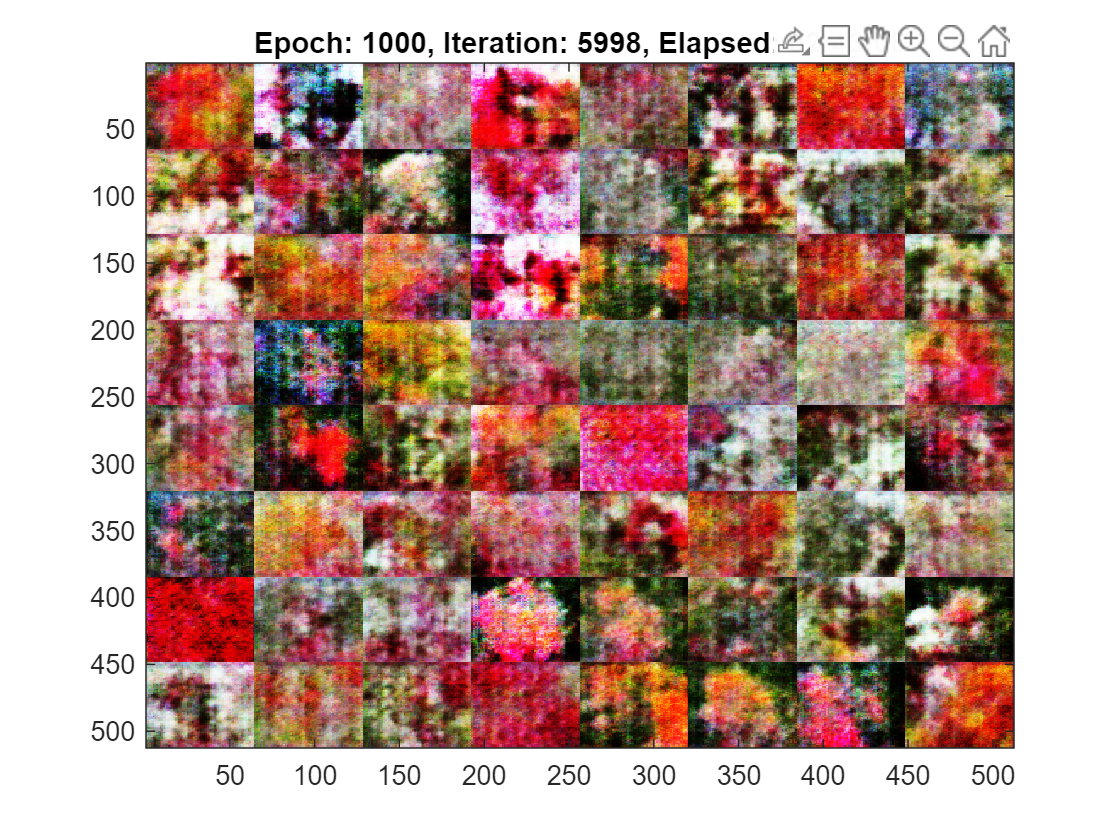

ZValidation = randn(1,1,numLatentInputs,64,'single');
dlZValidation = dlarray(ZValidation,'SSCB');

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZValidation = gpuArray(dlZValidation);
end

figure
iteration = 0;
start = tic;


for i = 1:numEpochs
    
    i;
    
    % 数据仓库初始化
    reset(augimds);
    augimds = shuffle(augimds);
    
    % 遍历每一个mini-batches
    while hasdata(augimds)
        iteration = iteration + 1;
        
        % 读每个mini-batch的数据
        data = read(augimds);
        
        % 忽略最后一段零头数据
        if size(data,1) < miniBatchSize
            continue
        end
        
        % 生成器网络模型输入数据准备
        X = cat(4,data{:,1}{:});
        Z = randn(1,1,numLatentInputs,size(X,4),'single');
        
        % 数据归一化
        X = (single(X)/255)*2 - 1;
        
        % 将数据格式转换为SSCB格式
        % 'SSCB' (spatial, spatial, channel, batch).
        dlX = dlarray(X, 'SSCB');
        dlZ = dlarray(Z, 'SSCB');
        
        % 若在GPU上训练，将数据格式转换为gpuArray
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlX = gpuArray(dlX);
            dlZ = gpuArray(dlZ);
        end
        
        % 计算模型的梯度
        [gradientsGenerator, gradientsDiscriminator, stateGenerator] = ...
            dlfeval(@modelGradients, dlnetGenerator, dlnetDiscriminator, dlX, dlZ);
        dlnetGenerator.State = stateGenerator;
        
        % 更新判别器模型参数
        [dlnetDiscriminator.Learnables,trailingAvgDiscriminator,trailingAvgSqDiscriminator] = ...
            adamupdate(dlnetDiscriminator.Learnables, gradientsDiscriminator, ...
            trailingAvgDiscriminator, trailingAvgSqDiscriminator, iteration, ...
            learnRateDiscriminator, gradientDecayFactor, squaredGradientDecayFactor);
        
        % 更新生成器模型参数
        [dlnetGenerator.Learnables,trailingAvgGenerator,trailingAvgSqGenerator] = ...
            adamupdate(dlnetGenerator.Learnables, gradientsGenerator, ...
            trailingAvgGenerator, trailingAvgSqGenerator, iteration, ...
            learnRateGenerator, gradientDecayFactor, squaredGradientDecayFactor);
        
        % 每迭代2次，更新一次生成的图像
        if mod(iteration,2) == 0 || iteration == 1
            
            dlXGeneratedValidation = predict(dlnetGenerator,dlZValidation);
            
            I = imtile(extractdata(dlXGeneratedValidation));
            I = rescale(I);
            image(I)
            
            D = duration(0,0,toc(start),'Format','hh:mm:ss');
            title("Epoch: " + i + ", " + "Iteration: " + iteration + ", " + "Elapsed: " + string(D))
            
            drawnow
        end
    end
end

- **生成新图像**

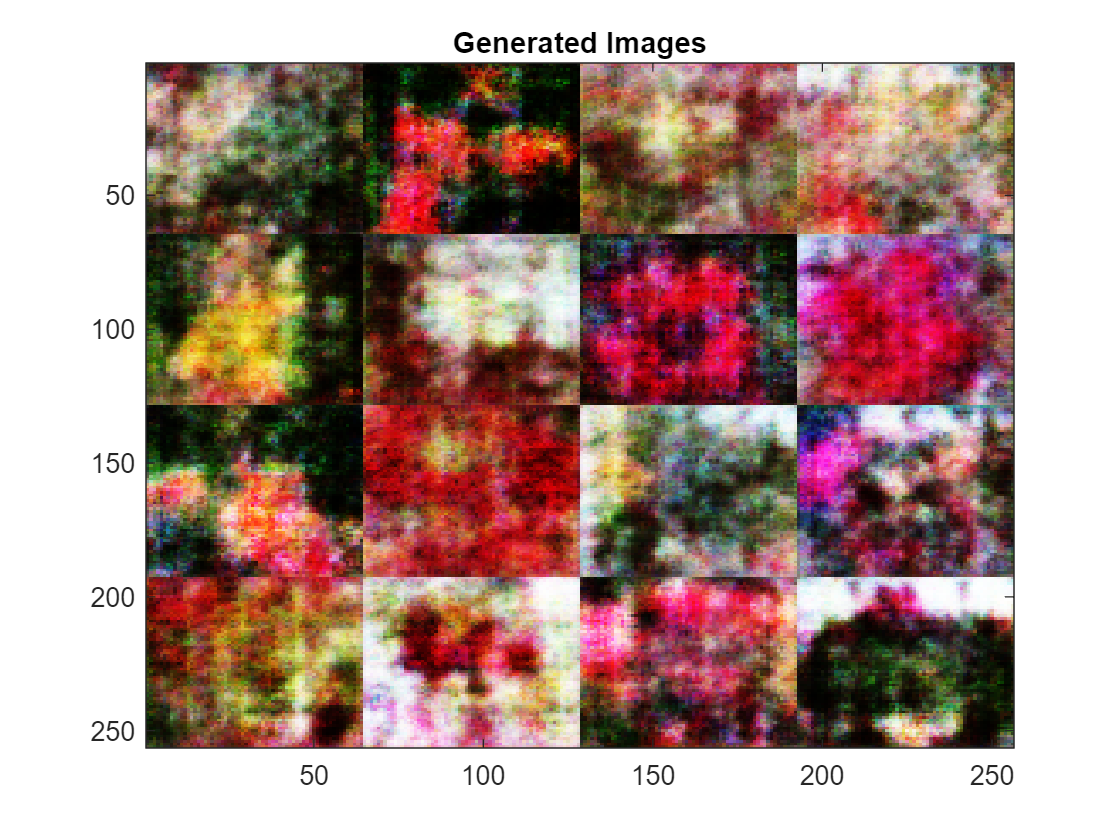

ZNew = randn(1,1,numLatentInputs,16,'single');
dlZNew = dlarray(ZNew,'SSCB');
 
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZNew = gpuArray(dlZNew);
end

% 生成新图像
dlXGeneratedNew = predict(dlnetGenerator,dlZNew);

% 显示
I = imtile(extractdata(dlXGeneratedNew));
I = rescale(I);
image(I)
title("Generated Images")

## Appendix-1：损失函数计算子函数

function [lossGenerator, lossDiscriminator] = ganLoss(dlYPred,dlYPredGenerated)

    % 计算判别器的损失
    lossGenerated = -mean(log(1-sigmoid(dlYPredGenerated)));
    lossReal = -mean(log(sigmoid(dlYPred)));
    lossDiscriminator = lossReal + lossGenerated;

    % 计算生成器的损失
    lossGenerator = -mean(log(sigmoid(dlYPredGenerated)));

end

## Appendix-2：梯度计算子函数

function [gradientsGenerator, gradientsDiscriminator, stateGenerator] = ...
    modelGradients(dlnetGenerator, dlnetDiscriminator, dlX, dlZ)

    % 计算判别器模型对真实数据的预测值
    dlYPred = forward(dlnetDiscriminator, dlX);

    % 计算判别器模型对假数据的预测值
    [dlXGenerated,stateGenerator] = forward(dlnetGenerator,dlZ);
    dlYPredGenerated = forward(dlnetDiscriminator, dlXGenerated);

    % 计算损失函数
    [lossGenerator, lossDiscriminator] = ganLoss(dlYPred,dlYPredGenerated);

    % 根据损失函数计算梯度
    gradientsGenerator = dlgradient(lossGenerator, dlnetGenerator.Learnables,'RetainData',true);
    gradientsDiscriminator = dlgradient(lossDiscriminator, dlnetDiscriminator.Learnables);

end